# Actividad 2.2 (Parametrizacion de trayectorias)

Para esta actividad directamente fui a coordenadas dependientes del tiempo, para ejemplificar usare la flor completamente pintada.

%Flor pintada

tiempo=[0:0.01:10];

El tiempo es de 0 a 10, lo cual nos da alrededor de 1000 puntos, esto nos dice la precision con la cual muestreamos nuestro angulo.

t= normalize(tiempo,"range",[0,pi]);

Se tiene que normalizar el tiempo, debido a que tenemos que pasar de angulo a tiempo. Por lo que son da de 0 a pi. En este caso, para las figuras geometricas sera de -pi a pi

x=5*cos(1004*t).*cos(t);
y=5*cos(1004*t).*sin(t);

Se contruye el comet con los puntos x y, para esto en nuestro primer valor determina la escala. En este caso es 5.

cos(1004*t) es la frecuencia de los giros, en este caso es mas grande que nuestros puntos, 1000, por lo que empieza a recortar nuestro circulo, generando la forma de la flor pero rellenandola.

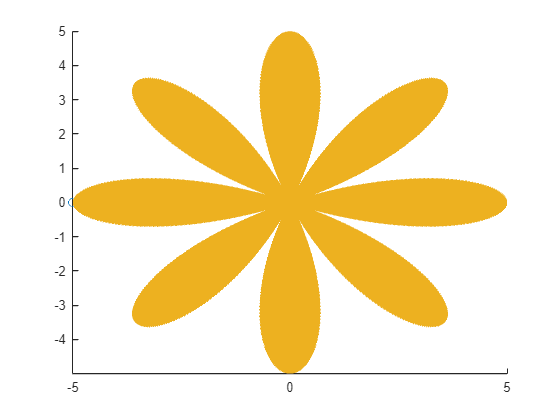

figure(10);
comet(x,y)

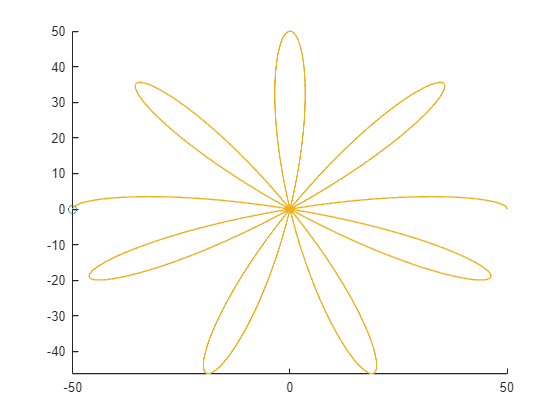


%Flor 1
tiempo1=[0:0.01:10];

t1= normalize(tiempo1,"range",[0,pi]);
x1=50*cos(8*t1).*cos(t1);
y1=50*cos(8*t1).*sin(t1);

figure(1);
comet(x1,y1)

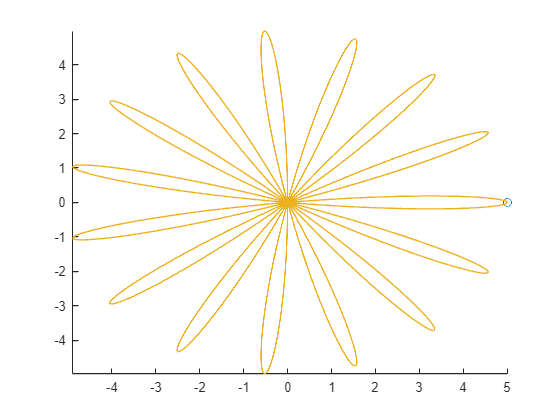


%Flor 2
tiempo2=[0:0.01:10];

t2= normalize(tiempo2,"range",[0,pi]);
x2=5*cos(15*t2).*cos(t2);
y2=5*cos(15*t2).*sin(t2);

figure(2);
comet(x2,y2)

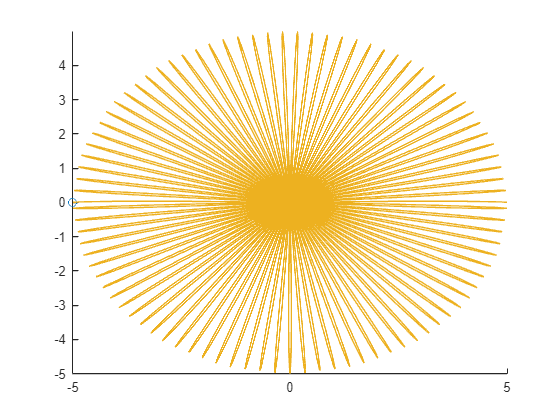


%Flor 3
tiempo3=[0:0.01:10];

t3= normalize(tiempo3,"range",[0,pi]);
x3=5*cos(90*t3).*cos(t3);
y3=5*cos(90*t3).*sin(t3);

figure(3);
comet(x3,y3)

Para las formas geometricas se utiliza un metodo lijeramente distinto debido a que no tenemos que usar funciones senoidales, si no que tenemos que dar los puntos los cuales tiene que recorer

en este caso divimos un circulo entre el numero de lados+1, por lo que en cuadrado son 5. 

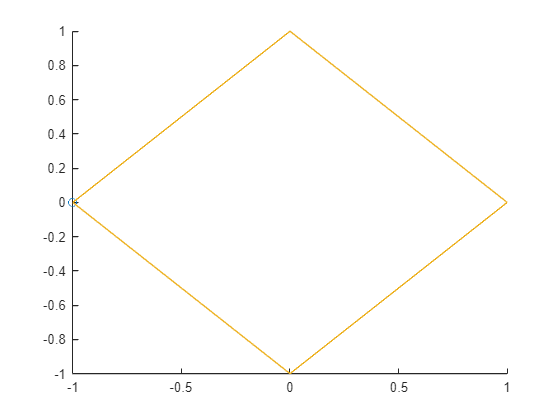

%Cuadrado
tiempo4=[1:1:5];

t4= normalize(tiempo4,"range",[-pi,pi]);
x4=ones(1,5).*cos(t4);
y4=ones(1,5).*sin(t4);

figure(4);
comet(x4,y4)

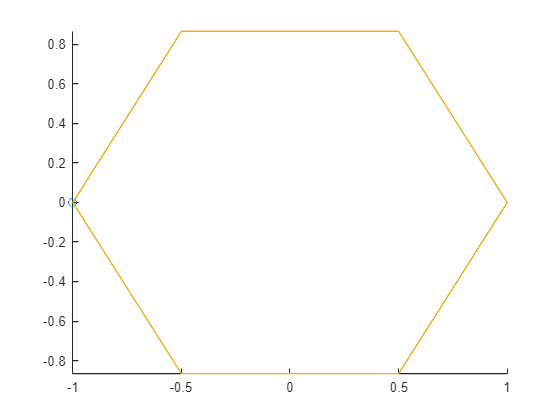


%Hexagono
tiempo5=[1:1:7];

t5= normalize(tiempo5,"range",[-pi,pi]);
x5=ones(1,7).*cos(t5);
y5=ones(1,7).*sin(t5);

figure(5);
comet(x5,y5)

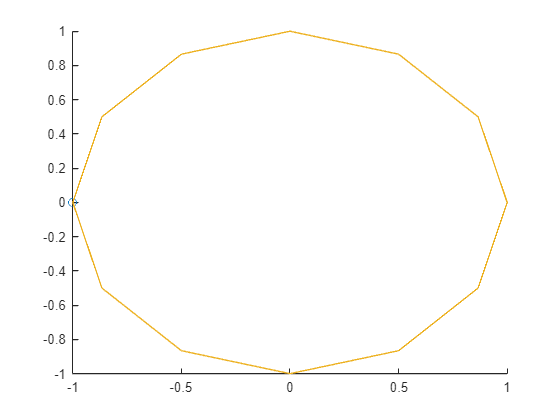


%Dodecagono
tiempo6=[1:1:13];

t6= normalize(tiempo6,"range",[-pi,pi]);
x6=ones(1,13).*cos(t6);
y6=ones(1,13).*sin(t6);

figure(6);
comet(x6,y6)